# SEIQR Model Simulation

Copyright 2022 Justice Inkoom at University of Mines and Technology

This is a simple **SEIQR** model of disease spread, implemented in MATLAB®. This approach is widely used to analyze infection data during the different stages of an epidemic outbreak. The population is divided into Susceptible (S), Exposed (E), Infectious (I), Quarantined (Q), and Recovered (R) individuals.

This particular model with its parameters are based on covid-19 outbreak in Ghana.

## The Model Overview

The equations that make up the SEIQR model are described by 5 ordinary differential equations as follows:


$$\begin{array}{l}
\frac{\textrm{ds}}{\textrm{dt}}=\alpha -\beta \ldotp s\ldotp \left(i+q\right)-\mu \ldotp s\\
\frac{\textrm{de}}{\textrm{dt}}=\beta \ldotp s\ldotp \left(i+q\right)-\left(\mu +\kappa +\gamma_2 +\nu \right)\ldotp e\\
\frac{\textrm{di}}{\textrm{dt}}=\kappa \ldotp e-\left(\mu +\delta_2 +\gamma_1 +\psi \right)\ldotp i\\
\frac{\textrm{dq}}{\textrm{dt}}=\nu \ldotp e+\psi \ldotp i-\left(\mu +\delta_1 +\gamma_3 \right)\ldotp q\\
\frac{\textrm{dr}}{\textrm{dt}}=\gamma_1 \ldotp i+\gamma_2 \ldotp e+\gamma_3 \ldotp q-\mu \ldotp r
\end{array}$$


## Model Simulation

**Model Parameters**

Play around with the parameters using the sliders and see the effect on the plot.

%% Initial parameters
A = 1.5;
a_0 = 0.012;
r_0 = 0.035;
B_0 = 0.04;
k_0 = 0.125;
b_0 = 0.0062;
r_1 = 0.412;
B_1 = 0.21;
k_1 = 0.025;
b_1 = 0.021;
g = 0.02;
B = 0.03;
u = 0.05;
a = 0.001;
b = 0.5;
c = 0.003;
d = 0.04;
k = 0.5;
Ba = 2;

s0 = 0.9;
x0 = 0.0001;
y0 = 0.0003;
z0 = 0.00021;
w0 = 0.002;

**Solve the ODE using **[ode45](https://www.mathworks.com/help/matlab/ref/ode45.html).

L0 = [s0; x0; y0; z0; w0];                % Initial conditions
T = 10;
tspan = [0 T];                        % Interval of Integration
[t,y] = ode45(@(t,y) sxyzw_model(t,y,A,a_0,r_0,B_0,k_0,b_0,r_1,B_1,k_1,b_1,g,B,u,a,b,c,d,k,Ba),tspan,L0);


For more info see the [Anonymous functions documentation](http://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html).

**Plots that show the results**

t

t =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


y

y =     0.9000    0.0001    0.0003    0.0002    0.0020
    0.9001    0.0001    0.0003    0.0002    0.0021
    0.9001    0.0001    0.0003    0.0002    0.0022
    0.9002    0.0001    0.0003    0.0002    0.0023
    0.9003    0.0001    0.0003    0.0002    0.0024
    0.9007    0.0001    0.0003    0.0002    0.0029
    0.9010    0.0001    0.0003    0.0002    0.0034
    0.9014    0.0001    0.0003    0.0002    0.0039
    0.9018    0.0001    0.0003    0.0002    0.0044
    0.9037    0.0001    0.0003    0.0002    0.0069


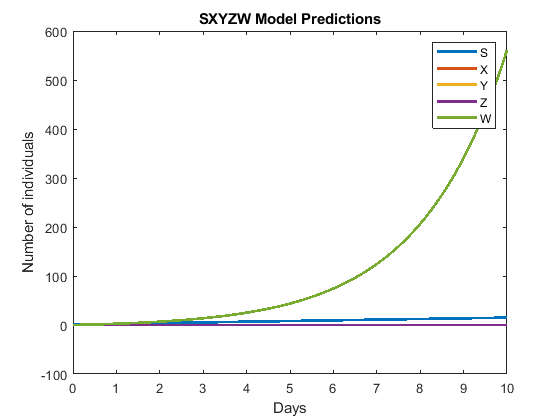

plot(t,y,'LineWidth',2);
xlabel('Days'); 
ylabel('Number of individuals');
legend('S','X','Y', 'Z','W');
title('SXYZW Model Predictions');

For more info see the [plot documentation](https://www.mathworks.com/help/matlab/ref/plot.html).

**Function **`seir_model`** that calculates the model evolution over a time period T.**

function dydt = sxyzw_model(t,y,A,a_0,r_0,B_0,k_0,b_0,r_1,B_1,k_1,b_1,g,B,u,a,b,c,d,k,Ba)
  S = y(1);
  X = y(2);
  Y = y(3);
  Z = y(4);
  W = y(5);
  % Equations of the model described above
  dS = (A+(a*S)-(a_0*S)-(g*S*X)) ;
  dX = ((g*S*X)+(c*X)-(r_0+(r_1*W)+(B*Y))*X) ;
  dY = ((B*X*Y)+(d*Y)-(B_0+(B_1*W)+(u*Z))*Y);
  dZ = ((u*Y*Z)+(k*Z)-(k_0+(k_1*W))*Z);
  dW = (Ba+(b*W)-(b_0*W)-(b_1*Z*X)-(b_1*W*Y)-(b_1*W*Z));
  dydt = [dS;dX;dY;dZ;dW];
end

## Further Evaluation

The three critical parameters in the model are beta, lambda and gamma.

Note that we have left several features unmodeled, for example: 

- Immunity loss rate ($\left.\alpha \right)$, where recovered individuals can get infected again.

- Some exposed individuals in "E" might move directly to the "R" category;

-  Some infected individuals in category "I" might not gain perfect immunity and so may move back to susceptible category "S." 

Despite these limitations, this basic SEIR model can provide some useful insights on the disease evolution.

  **Task.** Include additional features to your model and observe the effect on the plot.

                Example: To include Immunity loss rate ($\left.\alpha \right)$, the equations will be as follows:

                
$$\begin{array}{l}
\frac{\textrm{dS}}{\textrm{dt}}=-\beta \cdot \mathrm{S}\cdot \frac{I}{N}+\alpha \cdot \mathrm{R}\\
\frac{\textrm{dE}}{\textrm{dt}}=\beta \cdot \mathrm{S}\cdot \frac{I}{N}-\lambda \cdot E\\
\frac{\textrm{dI}}{\textrm{dt}}=\lambda \cdot E-\gamma \cdot \mathrm{I}\\
\frac{\textrm{dR}}{\textrm{dt}}=\gamma \cdot \mathrm{I}-\alpha \cdot \mathrm{R}
\end{array}$$
